File **circuit.png** shows a drawing of a source of current, a switch, a fuse and a lightbulb. Read the assignment descriptions concerning each part of the circuit and write your code inside the boxes. Make short commentaries for those lines of your code, which might be important for its understanding.

**Cleaning**

Clear the Command Window and the Workspace and close all graphical windows

clear, close all, clc

**Source current**

Load a current source signal from an external file **sourcecurrent.mat **into a workspace 

load("sourcecurrent.mat")

Save the first column of loaded variable **data**, which contains measured time values in seconds, as a new variable **t**. Save the second column of **data**, which is a measured source current values in amperes, as a new variable **I_t**. 

t=data(:,1);
I_t=data(:,2);%The output of both variables has been supressed, as it would only be unnecessary noise.

Save the first element of **I_t**,  which is an initial value of current, as a new variable **I0**. 

I0=I_t(1,1)%Output not supressed due to relation with the following part of the assignment.

I0 = 0.8660

Plot current vs. time as a blue dotted curve and the initial value of the current as a black dashed horisontal line. Set the thickness of both curves to 2pt. Make a legend positioned in the lower left corner. Show a title and axis labels with physical units. Set the font size of labels, title and legend to 20 pt.

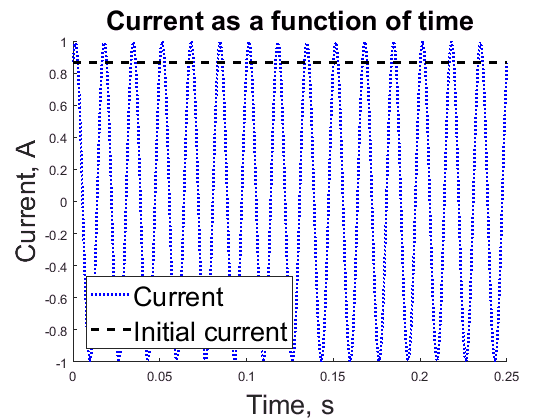

hold on
plot(t, I_t, 'b:', 'LineWidth', 2)
plot([0 0.25], [I0 I0], '--k', 'LineWidth', 2)%Horizontal line equal to I0
title('Current as a function of time', 'FontSize', 20)
xlabel('Time, s', 'FontSize', 20)
ylabel('Current, A', 'FontSize', 20)
legend({'Current', 'Initial current'}, 'Location', 'southwest', 'FontSize', 20)

**Electric switch**

In the lecture we used variable **s **with values** 'on' **and** 'off'** to describe switch states. Sometimes it is more convinient to use numbers instead of character variables: number **1 **instead of a character vector **'on'** and number **0 **instead of character vector **'off'**. 

*Task*: When the electric switch is on (**s=1**), there exists current in the circuit, **I=I0**. When it is off (**s=0**), there is no current **I=0**.  Use this description as a guide to write a program for an electrical switch in two steps: 

1. Give the variable **s** one of the above two values (**0** or **1**)

s=1

s = 1

2. Use keywords **switch**, **case** and **otherwise** to calculate the current **I**. Make sure that the current **I **changes its value depending on the switch state. Produce messages 'Switch is on' and 'Switch is off' depending on the state

switch s
    case 1
        I=I0
        'Switch is on'
    otherwise
        I=0
        'Switch is off'
end

I = 0.8660

ans = 'Switch is on'

**Voltage drop and heating in the fuse**

*Description*: the fuse is a FRS-R-1/10 600 V 0.1 A BUSSMAN Class RK5 600V Time Delay, which has about 50 milli-Ohms resistance (Lecture 4)

*Task*: Use the **if **and** else** keywords to determine whether the fuse will burn or stay intact. Give the resulting current value **I** in each case, remembering that

- If the switch considered in the previous section is 'on' and the fuse is intact, the current will still be equal to the battery current and you don't need to change it in the **if-else** statement below

- If the fuse is destroyed, the current will be zero

To show the state of the fuse, include the messages 'Fuse is damaged' and  'Fuse is intact' where appropriate. Calculate voltage drop in the fuse for each case depending on the current value **I** and fuse resistance. Finally, calculate the amount of heat generated by the fuse resistance. The results should take into account the case, when **I **exceeds **I_fuse=0.1 A**, and the case, when the current **I** is less or equal to **I_fuse**

I_fuse = 0.1;
if I>I_fuse
     I=0
    'Fuse is damaged'
elseif I<=I_fuse
    'Fuse is intact'
end

I = 0

ans = 'Fuse is damaged'


R = 50*10^-3;
V = I*R%Calculating the voltage drop with Ohm's law

V = 0


P=V*I%Calculating the effect in the resistance (which is equal to power loss due to heating)

P = 0

**Light bulb**

*Task*: Produce message 'Light is off' if there is no current in the circuit. Assuming the lightbulb will shine, if the current in the circuit is non-zero, produce message 'Light is on'. Use either keywords **if **and** else** or keywords **switch**, **case** and **otherwise** 

if I==0%Only under the circumstance that the current is exactly zero (as defined by previous sequences) is the light off.
    'Light is off'
else
    'Light is on'
end

ans = 'Light is off'

**Testing**

Test your solution with the following four values for **s **and **I0:**

- **s = 1 **and **I0 = 0.0**

- **s = 0 **and **I0 = 0.09**

- **s = 1 **and **I0 = 0.09**

- **s = 0** and **I0 = 0.11**

- **s = 1** and **I0 = 0.11**

Use this test to verify your results. Does the output make sense in each of the cases?

**Flowchart**

Draw a flowchart of the code contained in the sections **Electric switch,** **Voltage drop and heating in the fuse** and **Light bulb.** You can submit your drawing at the next lecture or by email. You can also submit it together with this document via SDU Assignment before the next lecture, which will take place on November, 17. 